# F3_Run_ABX_Probiotic_ShortTerm.m

**Goal:** Compare short-term/acute dosing of probiotic to antibiotics, or combination antibiotic plus probiotic.

**Requirements**: 

MATLAB Toolboxes: Parallel Computing, Bioinformatics, Symbolic Math

Custom Scripts: Add the `probiotic_code/` folder to your path

Model inputs as defined in `define_Common_Simulation_Inputs `(*Defines virtual patient population, simulation inputs)*

*Functions:*` simulate_Clinical_Regimens.m, superbar.m`: If you do not have superbar, the plots wil not be generated. Superbar can be downloaded here: [https://www.mathworks.com/matlabcentral/fileexchange/57499-superbar](https://www.mathworks.com/matlabcentral/fileexchange/57499-superbar) 

## 1. Load Model Defaults

clear; clc;
ws_name = 'input_files/SSConfig-Analysis-HMP-Virtual-Population.mat';
simulationType = "combo";
[POPinfo,PROBinfo,ABXinfo,~] = define_Common_Simulation_Inputs(ws_name,simulationType);
output_fdr = 'result_workspaces/';

`POPinfo`: struct that defines virtual patient population

- `virtualPatientParameter`s: # patients x 20 parameter matrix generated by LHS

- `virtualPatientComposition`: 1 x # patients cell of analytically predicted steady-state absolute abundances of nAB, Li, oLB (predicted without considering probiotic in community)

- `initialComposition`: scaling factor to "displace" from the predicted composition (POPinfo.virtualPatientComposition). For example, 0.01 is a 1% decrease in abundance and 0.05 is a 0.5% increase from the predicted abundance

- `Indexes`: indexes relative to original LHS array

- `odeOptions`: "options" input for ode solvers

- `odeSolver:` ODE solver function handle (e.g., @ode45, @ode15s)

`PROBinfo`: struct that defines probiotic parameters

- `dose`: absolute abundance of probiotic when dosed into the base community (selected from relative abundance data observed in Dausset et al. 2018)

- `numberDoses`: total number of doses given

- `doseFrequency`: time separation (days) between each dose

- `strainCharacteristics`: parameter values for the tested strain

- `strainCharIndexes`: probiotic characteristics parameter indexes relative to full parameter set

`ABXinfo`: struct that defines the antibiotic parameters

- `AddABX`: true if ABX is used, false if ABX is not used

- `dose:` magnitude of the ABX effect (based on Mayer et al. 2015)

- `duration`: length of ABX regimen (5-7days)

## 2. Define Cinical Regimens

Creating Clinical Regimens: Requires input into structures for ABXinfo, PROBinfo, and POPinfo - NOTE: POPinfo now has "SIMinfo" incorporated, rather than being assigned it's own structure

**ABX Treatment + Probiotic**

A 7-day course of Metronidazole is simulated. The "dose" or decay rate was determined from digitized data published in Mayer et al. 2015: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4539900/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4539900/) 

Decay rates ranged from -0.95 d-1 to -5.44 d-1. I have used the average of this distribution, which was -2.64d-1. Other simulations are have considered the max value for *G. vaginalis* (-3.82 d^-1).

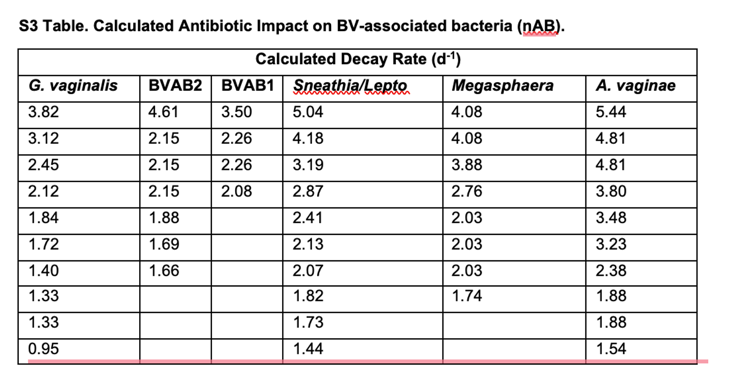

% ~~~~~~~~~~~~~~~~~ ABX + ACUTE PROBIOTIC ~~~~~~~~~~~~~~~~~
ABXinfo.addABX = true; % true = add antibiotic, false = skip
ABXinfo.dose = -2.64; % decay rate
ABXinfo.duration = 7; % days

PROBinfo.dose = 7.5; % relative unit
PROBinfo.numberDoses = 7; % days
PROBinfo.doseFrequency = 1; % every XX days
PROBinfo.strainCharIndexes =  [4,8,12,16,17,18,19,20];
PROBinfo.strainCharacteristics = [0.5 0 0 0 -0.01 0 0 -0.022];

**Antibiotic (No Probiotic)**

Update entries to indicate there is no probiotic (set dose = 0, numberDoses and doseFrequency = 1). By doing so, this ensuress that the evaluation points occur at the appropriate time points relative to therapy cessation.

% ~~~~~~~~~~~~~~~~~ ABX + NO PROBIOTIC ~~~~~~~~~~~~~~~~~
% all other simulation info is the same, only need to change dose to zero
PROBinfo.dose = 0; % relative unit 
PROBinfo.numberDoses = 1;
PROBinfo.doseFrequency = 1;

ABXOnlyDesign = {ABXinfo,PROBinfo,POPinfo};

**Probiotic (No Antibiotic)**

Update entries too indicate there is no antibiotic and indicate the probiotic information.

% ~~~~~~~~~~~~~~~~~ NO ABX + ACUTE PROBIOTIC ~~~~~~~~~~~~~~~~~
ABXinfo.addABX = false; % true = add antibiotic, false = skip
ABXinfo.dose = 0; % decay rate
ABXinfo.duration = 0; % days

PROBinfo.dose = 7.5; % relative unit
PROBinfo.numberDoses = 7; % days
PROBinfo.doseFrequency = 1; % every XX days

ProbioticOnlyDesign = {ABXinfo,PROBinfo,POPinfo};

Compile the deisgns into a cell array to iterate through.

% ~~~~~~~~~~~~~~~~~ COMPILE DESIGNS INTO CELL ARRAY ~~~~~~~~~~~~~~~~~
testDesigns = {ProbioticOnlyDesign,ABXProbioticDesign,ABXOnlyDesign};

## 3. Run the Different Test Designs

% ITERATE THROUGH EACH REGIMEN TYPE
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

output_ws_nm = 'F3_ABX_Probiotic_ShortTerm.mat';
testDesignNames = {'Only Probiotic','ABX + Probiotic','Only ABX'};

t = tic;
numPatients = size(POPinfo.virtualPatientParameters,1);
all_select_outcomes = NaN(length(testDesigns),numPatients,8,5);
all_warnall = NaN(length(testDesigns),numPatients);
for i = 1:length(testDesigns)
    tmp = testDesigns{i};
    ABXinfo = tmp{1};
    PROBinfo = tmp{2};
    POPinfo = tmp{3};
    [select_outcomes, ~, warnall, ...
        ~] = simulate_Clinical_Regimens(ABXinfo,PROBinfo,POPinfo);

RUNNING ... #17
RUNNING ... #34
RUNNING ... #51
RUNNING ... #68
RUNNING ... #85
RUNNING ... #102
RUNNING ... #16
RUNNING ... #15
RUNNING ... #14
RUNNING ... #13
RUNNING ... #12
RUNNING ... #11
RUNNING ... #10
RUNNING ... #9
RUNNING ... #8
RUNNING ... #7
RUNNING ... #6
RUNNING ... #5
RUNNING ... #4
RUNNING ... #3
RUNNING ... #2
RUNNING ... #1
RUNNING ... #33
RUNNING ... #32
RUNNING ... #31
RUNNING ... #30
RUNNING ... #29
RUNNING ... #28
RUNNING ... #27
RUNNING ... #26
RUNNING ... #25
RUNNING ... #24
RUNNING ... #23
RUNNING ... #22
RUNNING ... #21
RUNNING ... #20
RUNNING ... #19
RUNNING ... #18
RUNNING ... #50
RUNNING ... #49
RUNNING ... #48
RUNNING ... #47
RUNNING ... #46
RUNNING ... #45
RUNNING ... #44
RUNNING ... #43
RUNNING ... #42
RUNNING ... #41
RUNNING ... #40
RUNNING ... #39
RUNNING ... #38
RUNNING ... #37
RUNNING ... #36
RUNNING ... #35
RUNNING ... #576
RUNNING ... #575
RUNNING ... #574
RUNNING ... #573
RUNNING ... #572
RUNNING ... #571
RUNNING ... #570
RUNNING ... #569
RUNNING 


    all_select_outcomes(i,:,:,:) = select_outcomes;

2.5473 minutes


    all_warnall(i,:) = warnall == "";
end
tend = toc(t);
disp(strcat(num2str(tend/60), " minutes"))

save(strcat(output_fdr,output_ws_nm), 'all_select_outcomes', 'all_warnall',...
    "testDesignNames",'testDesigns')

## 4. Visualize Results

Results were evaluated at four points. The result viewed here is for the -3.82 decay rate dose.

- 0 days post (#2)

- 1 month post (#5)

- 3 months post (#6)

- 6 months post (#7)

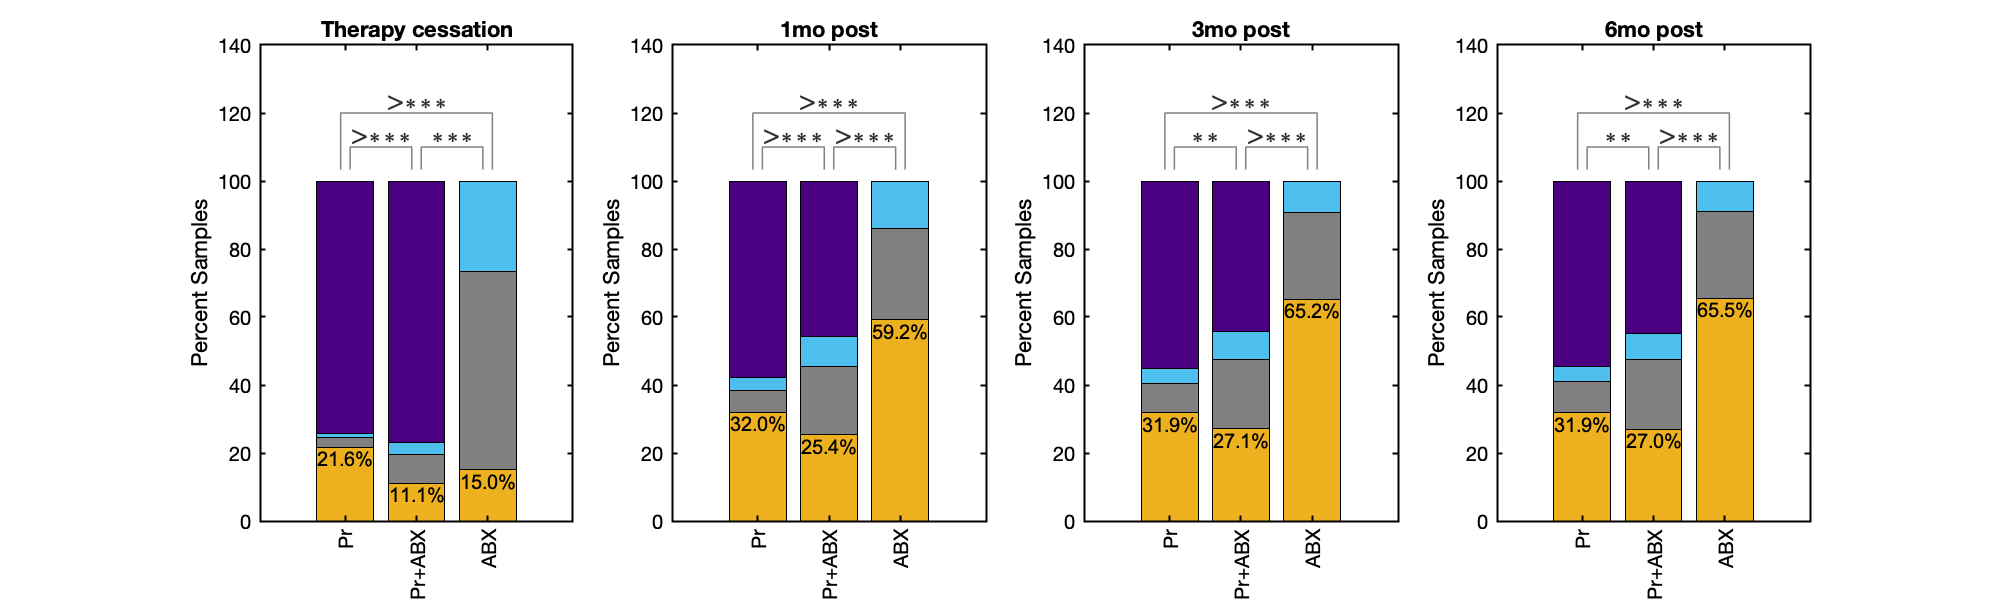

output_fdr = 'result_workspaces/F3/'; % default output workspace location
load(strcat(output_fdr,'F3_ABX_Probiotic_ShortTerm.mat'))

timePoints = [2 5 6 7]; % timepoints to analyze
f = figure;
[Counts,all_PvaluesLB,all_PvaluesBV] = ...
    plot_ProbioticABXComparisons(all_select_outcomes,all_warnall,...
    testDesigns,testDesignNames,timePoints);
set(f,'Visible','on','units','pixels','position',[1 1 1000 300])

Pairwise chi-square tests were used to evaluate differences in failure rate (nAB dominance at evaluated time point). The outputs for `plot_ProbioticABXComparisons` include:

- `Counts`: 3D array [# timepoints x # regimens x # response types] counts of each response type evaluated (nAB, Li, oLB, Probiotic dominanted)

- `all_PvaluesLB`: 3D array [# timepoints x # regimens x # regimens], symmetrical p-value matrix for each timepoint evaluated comparing all response types

- `all_PvaluesBV`: 3D array [# timepoints x # regimens x # regimens], symmetrical p-value matrix for each timepoint evaluated comparing all BV+/BV- (nAB dominant / *Lactobacillus *spp. dominant)